clear all
% data=textread('AHRS/data/dynamic.txt');
data=textread('AHRS/data/odometry.txt');
time=data(:,1);
dT=diff(time);
dT=[dT(1);dT];
data = data(:,2:end);
% temp=data(:,2);
% data(:,2)=data(:,1);
% data(:,1)=temp;
% data(:,3)=-data(:,3);
% temp=data(:,5);
% data(:,5)=data(:,4);
% data(:,4)=temp;
% data(:,6)=-data(:,6);

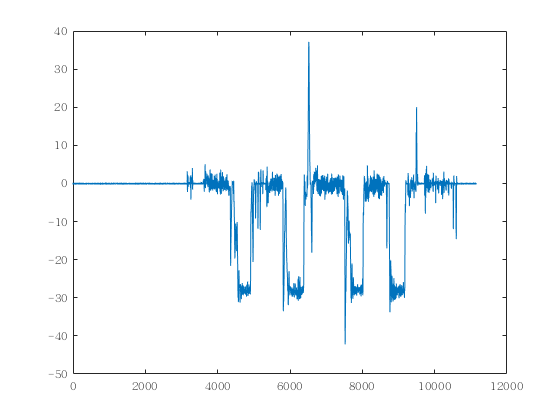

%角速度去零飘处理
staticNum=300;static=299;
wx=(data(1:end,1)-mean(data(staticNum-static:staticNum,1)))*180.0/pi;
wy=(data(1:end,2)-mean(data(staticNum-static:staticNum,2)))*180.0/pi;
wz=(data(1:end,3)-mean(data(staticNum-static:staticNum,3)))*180.0/pi;
plot(wz)

%加速度计归一化处理
axRaw=data(1:end,4);
ayRaw=data(1:end,5);
azRaw=data(1:end,6);
normAcc=sqrt(sum(data(1:end,4:6).^2,2));
ax=axRaw./normAcc;
ay=ayRaw./normAcc;
az=azRaw./normAcc;

%%积分量初始化
initEuler=[atan2d(-ay(1),-az(1)) asind(ax(1)) zeros(length(ax(1)),1)];%欧拉角初始化
initQuaternion=euler2quat_self(initEuler);%四元数初始化
quaternion=initQuaternion;
quaternionMahony=initQuaternion;

n=length(wx);%数据长度
GyroAngle=zeros(n,3);%纯陀螺仪算出的角度
MahonyAngle=zeros(n,3);%融合加速度计后算出的角度
q0=zeros(n,1);q1=zeros(n,1);q2=zeros(n,1);q3=zeros(n,1);%mahony滤波器中间变量值
exInt=zeros(n,1);eyInt=zeros(n,1);ezInt=zeros(n,1);%mahony滤波器中间变量值
Kp=-10;%mahony滤波器中间变量值
Ki=0.000;%mahony滤波器中间变量值

%陀螺仪积分过程
for i=1:n
    %纯陀螺仪角速度积分
    quaternion=quatInt(quaternion,[wx(i);wy(i);wz(i)],dT(i));
    GyroAngle(i,1:3)=quat2euler_self(quaternion);
end
%纯加速度计算出的角度
AccAngle=[atan2d(-ay,-az) asind(ax) zeros(length(ax),1)];
%积分过程
for i=1:n
    acc = [ax(i) ay(i) az(i)];
    %根据运动情况，自适应mahony滤波器参数。实际运动情况越明显，融合力度越小；越靠近静止状态，融合力度越大。
    q0(i)=quaternionMahony(1);q1(i)=quaternionMahony(2);q2(i)=quaternionMahony(3);q3(i)=quaternionMahony(4);
    vx(i) = 2*(q1(i)*q3(i) - q0(i)*q2(i));
    vy(i) = 2*(q0(i)*q1(i) + q2(i)*q3(i));
    vz(i) = q0(i)*q0(i) - q1(i)*q1(i) - q2(i)*q2(i) + q3(i)*q3(i);
    
    ex(i)=ay(i)*vz(i)-az(i)*vy(i);
    ey(i)=az(i)*vx(i)-ax(i)*vz(i);
    ez(i)=ax(i)*vy(i)-ay(i)*vx(i);
    
    if i>1
        exInt(i) = exInt(i-1) + ex(i)*dT(i);
        eyInt(i) = eyInt(i-1) + ey(i)*dT(i);
        ezInt(i) = ezInt(i-1) + ez(i)*dT(i);
    end
    
    gx(i) = wx(i) + Kp*ex(i) + exInt(i)*Ki;
    gy(i) = wy(i) + Kp*ey(i) + eyInt(i)*Ki;
    gz(i) = wz(i) + Kp*ez(i) + ezInt(i)*Ki;
    %对mahony滤波器融合加速度数据后的角速度进行积分
    quaternionMahony=quatInt(quaternionMahony,[gx(i);gy(i);gz(i)],dT(i));
    MahonyAngle(i,1:3)=quat2euler_self(quaternionMahony);
end


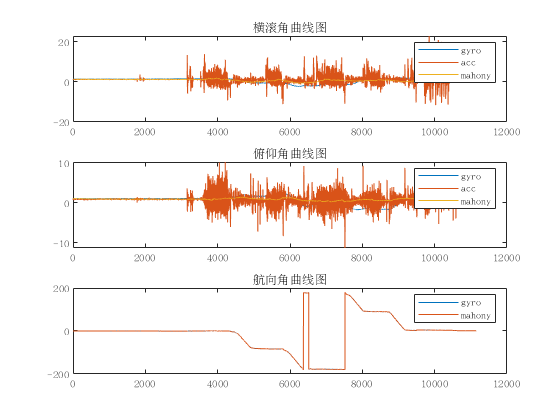

%画图
figure
subplot(311);
plot(GyroAngle(:,1));hold on;
plot(AccAngle(:,1));hold on;
plot(MahonyAngle(:,1));
title('横滚角曲线图')
legend('gyro','acc','mahony');
subplot(312);
plot(GyroAngle(:,2));hold on;
plot(AccAngle(:,2));hold on;
plot(MahonyAngle(:,2));
title('俯仰角曲线图')
legend('gyro','acc','mahony');
subplot(313);
plot(GyroAngle(:,3));hold on;
plot(MahonyAngle(:,3));
title('航向角曲线图')
legend('gyro','mahony');